clc; close all; clearvars;

% Number class
M=2;

## Generate the subset X1 of X, which contains the data points from the first class

m11=[1.25 1.25]'; m12=[2.75 2.75]';m13=[2 6]';
m1=[m11 m12 m13];
S1(:,:,1)=0.1*eye(2);
S1(:,:,2)=0.2*eye(2);
S1(:,:,3)=0.3*eye(2);
P1=[0.4 0.4 0.2];
N1=500;
sed=0;
[X1,y1]=mixt_model(m1,S1,P1,N1,sed);

## The subset X2 of X, with the points from the second class is generated similarly (use again sed = 0)

m21=[1.25 2.75]'; m22=[2.75 1.25]';m23=[4 6]';
m2=[m21 m22 m23];
S2(:,:,1)=0.1*eye(2);
S2(:,:,2)=0.2*eye(2);
S2(:,:,3)=0.3*eye(2);
P2=[0.2 0.3 0.5];
N2=500;
sed=0;
[X2,y2]=mixt_model(m2,S2,P2,N2,sed);

## Dataset Z is generated in two steps,i.e., 500 points are first generated from

the first class (dataset Z1)

mZ11=[1.25 1.25]'; mZ12=[2.75 2.75]';mZ13=[2 6]';
mZ1=[mZ11 mZ12 mZ13];
SZ1(:,:,1)=0.1*eye(2);
SZ1(:,:,2)=0.2*eye(2);
SZ1(:,:,3)=0.3*eye(2);
wZ1=[0.4 0.4 0.2];
NZ1=500;
sed=100;
[Z1,yz1]=mixt_model(mZ1,SZ1,wZ1,NZ1,sed);

## The remaining 500 points from the second class (dataset Z2) are generated similarly (use

## again sed = 100).

mZ21=[1.25 2.75]'; mZ22=[2.75 1.25]';mZ23=[4 6]';
mZ2=[mZ21 mZ22 mZ23];
SZ2(:,:,1)=0.1*eye(2);
SZ2(:,:,2)=0.2*eye(2);
SZ2(:,:,3)=0.3*eye(2);
wZ2=[0.2 0.3 0.5];
NZ2=500;
sed=100;
[Z2,yz2]=mixt_model(mZ2,SZ2,wZ2,NZ2,sed);

## Generate dataset Z

Z=[Z1 Z2];

## 1. Estimate the Gaussian mixture model of each class

m11_ini=[0; 2]; m12_ini=[5; 2]; m13_ini=[5; 5];
m1_ini=[m11_ini m12_ini m13_ini];
S1_ini=[0.15 0.27 0.4];
w1_ini=[1/3 1/3 1/3];
m21_ini=[5; 2]; m22_ini=[3; 4]; m23_ini=[2; 5];
m2_ini=[m21_ini m22_ini m23_ini];
S2_ini=[0.15 0.27 0.35];
w2_ini=[1/3 1/3 1/3];

m_ini{1}=m1_ini;
m_ini{2}=m2_ini;
S_ini{1}=S1_ini;
S_ini{2}=S2_ini;
w_ini{1}=w1_ini;
w_ini{2}=w2_ini;
[m_hat,S_hat,w_hat,P_hat]=EM_pdf_est([X1 X2],[ones(1,500) 2*ones(1,500)],m_ini,S_ini,w_ini);

## 2. Use function mixture_Bayes to classify the data vectors of Z and function compute_error to

## obtain the classification error.

for j=1:2
    le=length(S_hat{j});
    te=[];
    for i=1:le
        te(:,:,i)=S_hat{j}(i)*eye(2);
    end
    S{j}=te;
end
[y_est]=mixture_Bayes(m_hat,S,w_hat,P_hat,Z);

## 3. Compute the confusion matrix

Index set for plotconfusion Label Tests Data Set

tz=[ones(1, NZ1) 2*ones(1, NZ2)]; %Etiquetas data set de test
ind_t1=find(tz==1);ind_t2=find(tz==2); 
Targets=zeros(M,NZ1+NZ2);
Targets(1,ind_t1)=1; Targets(2,ind_t2)=1;

## Label EM estimate + Bayes Classifier

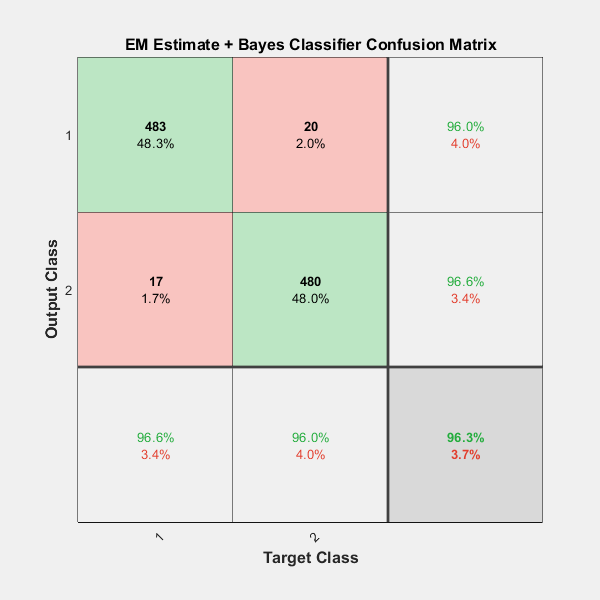

ind_1=find(y_est==1); ind_2=find(y_est==2); 
Outputs=zeros(M,N2);
Outputs(1,ind_1)=1; Outputs(2,ind_2)=1; 
% Plot Confusion
figure; plotconfusion(Targets,Outputs,'EM Estimate + Bayes Classifier')